%Alperen Öztürk (2575868) , Ömer Faruk Özmermer (2516789) , Muhammed Emin Özgün(2575843)
load("data.mat");

%POSITION DATA
lat=Position.latitude;
lon=Position.longitude;
positionDatetime=Position.Timestamp;
spd = Position.speed;

%ACCELERATION DATA
Xacc = Acceleration.X;
Yacc = Acceleration.Y;
Zacc = Acceleration.Z;
accelDatetime=Acceleration.Timestamp;

%TIME CONVERSION
positionTime=timeElapsed(positionDatetime);
accelTime=timeElapsed(accelDatetime);


earthCirc = 40175017; % The equatorial circumference of Earth, m
totaldis = 0; % m

for i = 1: (length(lat)-1)
 lat1 = lat(i);
 lat2 = lat(i+1);
 lon1 = lon(i);
 lon2 = lon(i+1);
 diff_ = distance(lat1, lon1, lat2, lon2);
 dis = (diff_/360)*earthCirc;
 totaldis = totaldis + dis;
end
disp(['The total distance traveled is: ', num2str(totaldis),' meters'])

The total distance traveled is: 212.5499 meters



%Steps based on position data
averagestep=0.78;
step_number=round(totaldis/averagestep);
disp(['You took ', num2str(step_number) ' steps. (based on position data)']);

You took 272 steps. (based on position data)


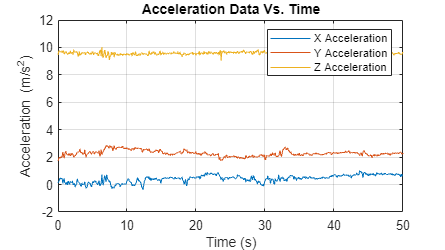


%Acceleration in different axis wrt time
figure('units','normalized','outerposition',[0 0 1 1]);
plot(accelTime,Xacc);
hold on;
plot(accelTime,Yacc);
plot(accelTime,Zacc);
xlim([0 50])
legend('X Acceleration','Y Acceleration','Z Acceleration');
xlabel('Time (s)')
ylabel('Acceleration (m/s^2)');
title('Acceleration Data Vs. Time');
grid;
hold off


acc_mag=sqrt(Xacc.^2+Yacc.^2+Zacc.^2)

acc_mag =     9.6117
    9.8361
    9.9795
    9.8849
    9.8777
    9.8719
    9.9821
    9.8945
   10.0067
    9.7518


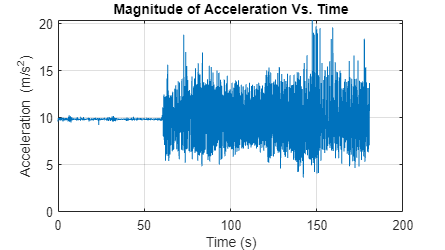


figure('units','normalized','outerposition',[0 0 1 1]);
plot(accelTime, acc_mag);
xlabel('Time (s)');
ylabel('Acceleration (m/s^2)');
title('Magnitude of Acceleration Vs. Time');
grid;


constant_effect=mean(acc_mag(spd<0.3))

constant_effect = 9.8549

mag_0 = acc_mag-constant_effect

mag_0 =    -0.2433
   -0.0188
    0.1245
    0.0300
    0.0227
    0.0169
    0.1271
    0.0395
    0.1517
   -0.1032


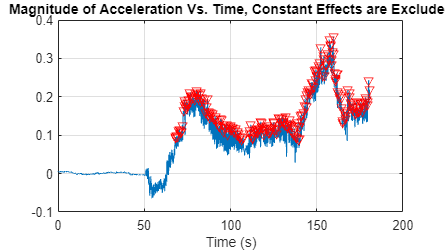

%mag_0 = movmean(mag_0,5);
mag_0 = movmean(mag_0,200);


minPeakHeight = std(mag_0); % standard deviation of acceleration.
[pks,locs] = findpeaks(mag_0,'MINPEAKHEIGHT',minPeakHeight);

figure('units','normalized','outerposition',[0 0 1 1]);
plot(accelTime,mag_0);
hold on;
plot(accelTime(locs), pks, 'r', 'Marker', 'v', 'LineStyle', 'none');
xlabel('Time (s)');
title('Magnitude of Acceleration Vs. Time, Constant Effects are Excluded');
grid;
hold off;


numSteps= numel(pks);   
disp(['You took ', num2str(numSteps) ' steps. (based on acceleration data)']);

You took 231 steps. (based on acceleration data)




positionTimeStanding=positionTime(spd<0.3)

positionTimeStanding =          0
    1.0000
    2.0000
    3.0000
    3.9990
    4.9990
    5.9990
    6.9990
    7.9990
    8.9990


spdStanding=spd(spd<0.3)

spdStanding =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


positionTimeWalking=positionTime((0.3<spd) & (spd<1.5))

positionTimeWalking =    60.9990
   61.9990
   62.9990
   63.9990
   64.9990
   65.9990
   66.9990
   67.9990
   68.9990
   69.9990


spdWalking=spd((0.3<spd) & (spd<1.5))

spdWalking =     0.4650
    0.7950
    0.9400
    0.7000
    1.0000
    0.7490
    0.7820
    0.9340
    0.8400
    0.8420


positionTimeRunning=positionTime(1.5<spd)

positionTimeRunning =    93.9980
  102.9980
  110.9980
  119.9980
  120.9980
  122.9980
  124.9980
  125.9980
  126.9980
  127.9980


spdRunning=spd(1.5<spd)

spdRunning =     1.6970
    1.6810
    1.5750
    1.5480
    1.7770
    1.8340
    1.8200
    1.5150
    1.8820
    1.5410


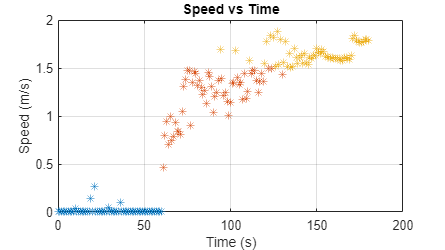

figure('units','normalized','outerposition',[0 0 1 1]);
plot(positionTimeStanding, spdStanding, "*");
hold on;
plot(positionTimeWalking, spdWalking, "*");
hold on;
plot(positionTimeRunning, spdRunning, "*");
xlabel('Time (s)');
ylabel('Speed (m/s)');
title("Speed vs Time");
grid;
hold off;

mapping(Position)